## EBSD

plotx2east
mtexdata forsterite

 
ebsd = EBSD
 
 Phase  Orientations     Mineral         Color  Symmetry  Crystal reference frame
     0   58485 (24%)  notIndexed                                                 
     1  152345 (62%)  Forsterite  LightSkyBlue       mmm                         
     2   26058 (11%)   Enstatite  DarkSeaGreen       mmm                         
     3   9064 (3.7%)    Diopside     Goldenrod     12/m1       X||a*, Y||b*, Z||c
 
 Properties: bands, bc, bs, error, mad, x, y
 Scan unit : um
 


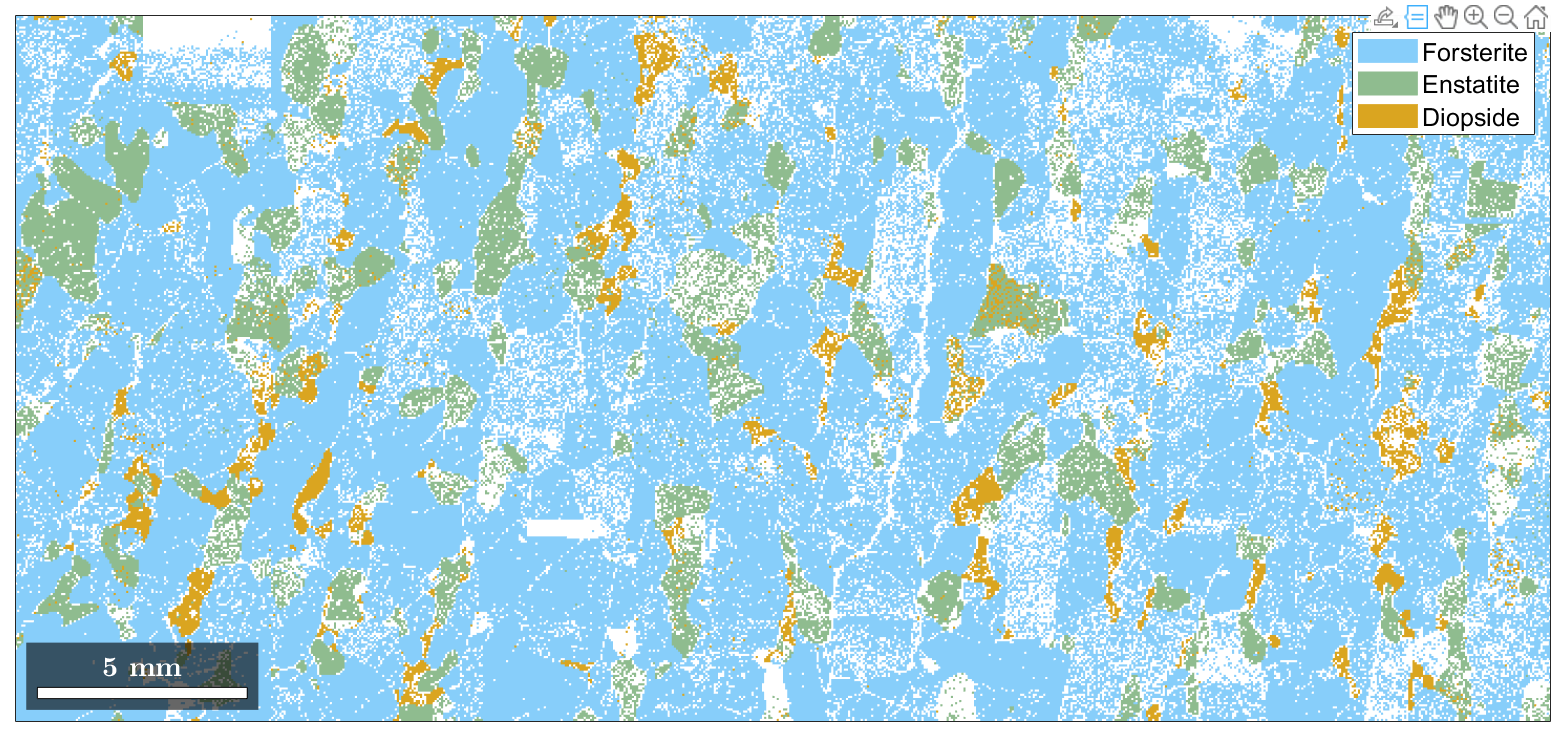

plot(ebsd)

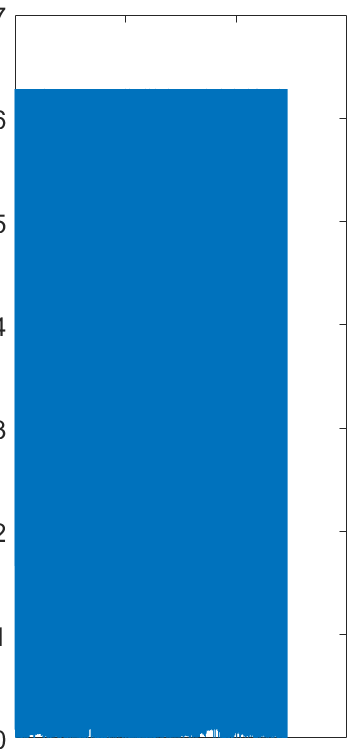

ori = ebsd.rotations;

trial = ebsd.rotations.phi1;
plot(trial)

 
odf = SO3FunHarmonic (xyz → xyz)
  bandwidth: 25
  weight: 1
 


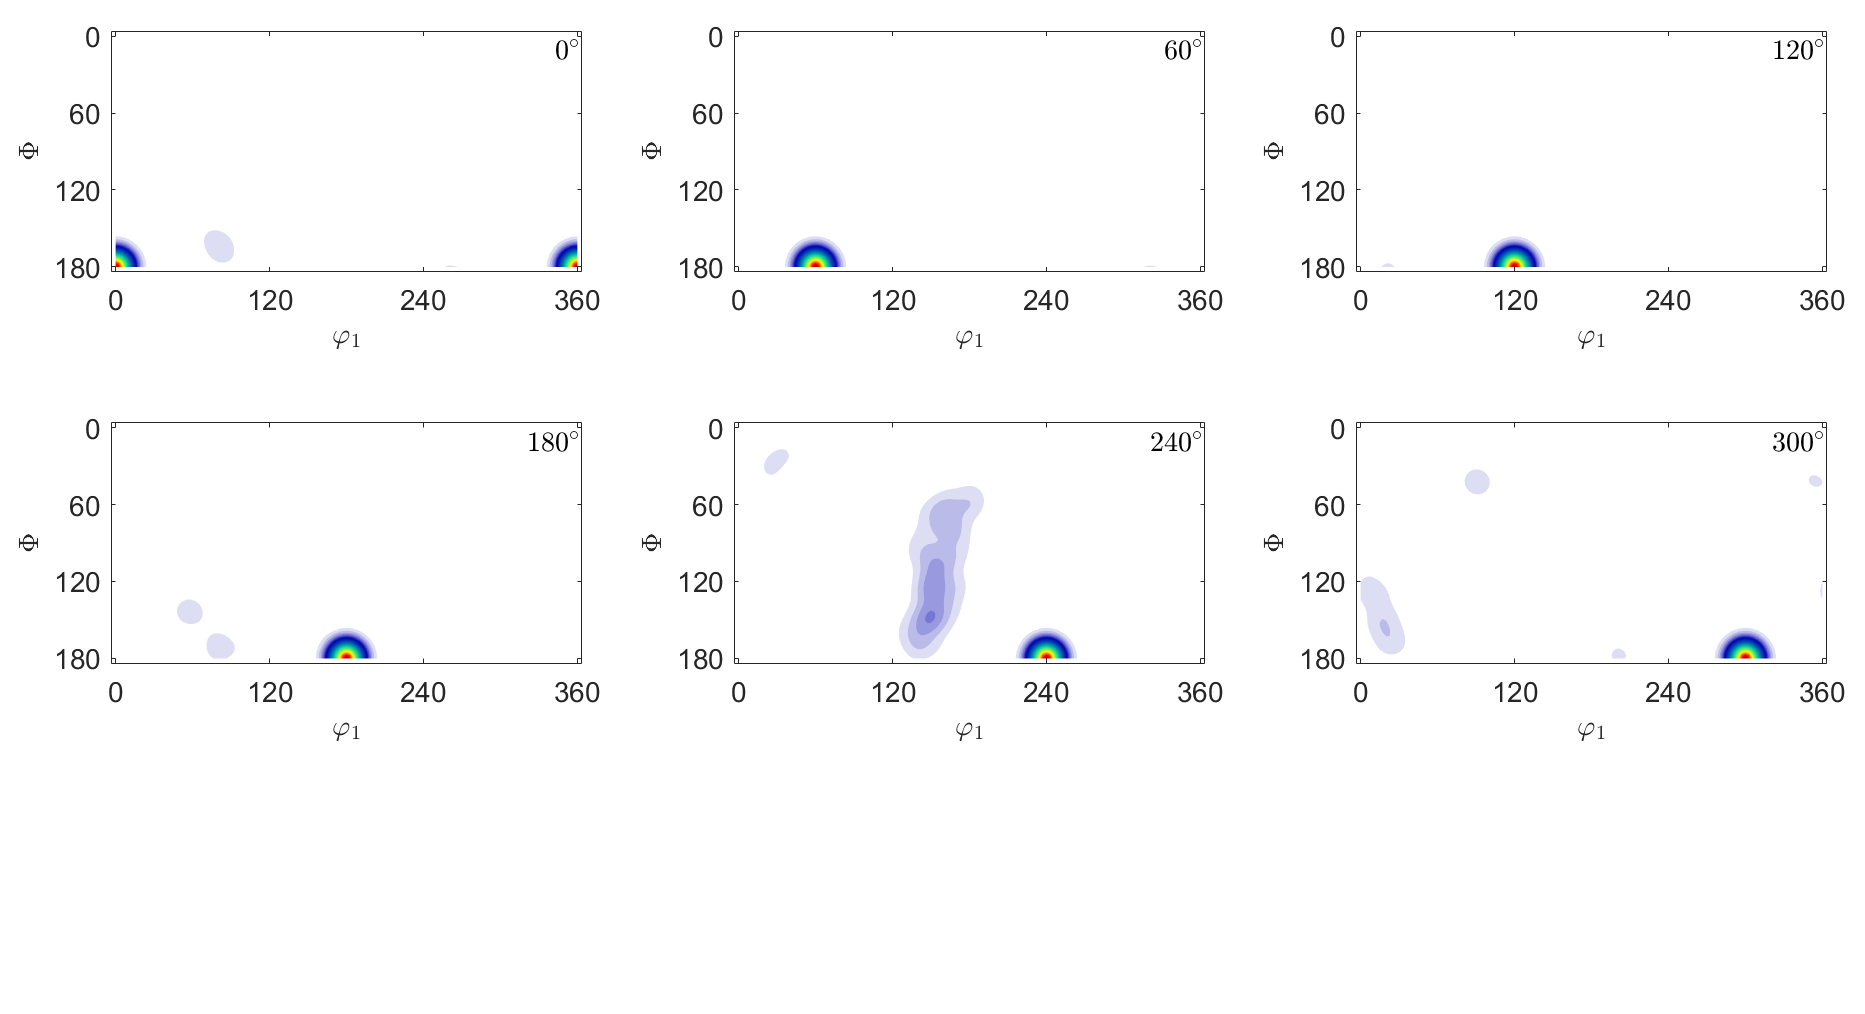

odf = calcDensity(ori)
plot(odf)

pixelf = ebsd(1)

 
pixelf = EBSD
 
 Phase  Orientations     Mineral         Color  Symmetry  Crystal reference frame
     1      1 (100%)  Forsterite  LightSkyBlue       mmm                         
 
 Id   Phase   phi1   Phi   phi2   bands    bc    bs   error   mad   x   y
  1       1     95    42    294       7   138   255       0   0.1   0   0
 Scan unit : um
 


pixele = ebsd(48)

 
pixele = EBSD
 
 Phase  Orientations    Mineral         Color  Symmetry  Crystal reference frame
     2      1 (100%)  Enstatite  DarkSeaGreen       mmm                         
 
 Id   Phase   phi1   Phi   phi2   bands    bc    bs   error   mad      x   y
 48       2    151   146    309       7   114   171       0   0.4   2350   0
 Scan unit : um
 


pixeld = ebsd(50)

 
pixeld = EBSD
 
 Phase  Orientations   Mineral      Color  Symmetry  Crystal reference frame
     3      1 (100%)  Diopside  Goldenrod     12/m1       X||a*, Y||b*, Z||c
 
 Id   Phase   phi1   Phi   phi2   bands    bc    bs   error   mad      x   y
 50       3    151   146    309       7   121   214       0   0.4   2450   0
 Scan unit : um
 


rgbf = pixelf.color*255

rgbf =    135   206   250


rgbe = pixele.color*255

rgbe =    143   188   143


rgbd = pixeld.color*255

rgbd =    218   165    32


ebsd trials mtek to double array

B = ebsd.phaseId;
Fors = ismember(B, 1);
Enst = ismember(B, 2);
Diops = ismember(B, 3);
find(Fors)

ans =     30
    72
    73
    74
    80
    83
    84
    93
   105
   122


find(Enst)

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


find(Diops)

ans =     47
    48
    49
    51
    52
   185
   186
   187
   188
   189


R = ebsd.rotations.Phi;
R1 = ebsd.rotations.phi1;
R2 = ebsd.rotations.phi2;
X = [R, R1, R2]

X =     0.7391    1.6637    5.1255
    0.7391    1.6683    5.1201
    0.7409    1.6644    5.1253
    0.7365    1.6679    5.1199
    0.7379    1.6652    5.1232
    0.7386    1.6679    5.1203
    0.7381    1.6665    5.1217
    0.7360    1.6677    5.1210
    0.7364    1.6672    5.1204
    0.7378    1.6677    5.1191


nOR = unique(X,"rows")

nOR =     0.0101    0.6999    4.0637
    0.0113    0.6480    4.1166
    0.0129    1.4041    3.3658
    0.0131    2.3749    5.5453
    0.0154    1.3757    3.3962
    0.0162    1.1765    3.5962
    0.0173    0.4948    4.2655
    0.0180    1.5482    3.2258
    0.0183    1.3650    3.4130
    0.0185    1.3193    3.4508


## ODF

mtexdata titanium

 
ebsd = EBSD
 
 Phase  Orientations           Mineral         Color  Symmetry  Crystal reference frame
     0   8100 (100%)  Titanium (Alpha)  LightSkyBlue       622       X||a, Y||b*, Z||c*
 
 Properties: ci, grainid, iq, sem_signal, x, y
 Scan unit : um
 


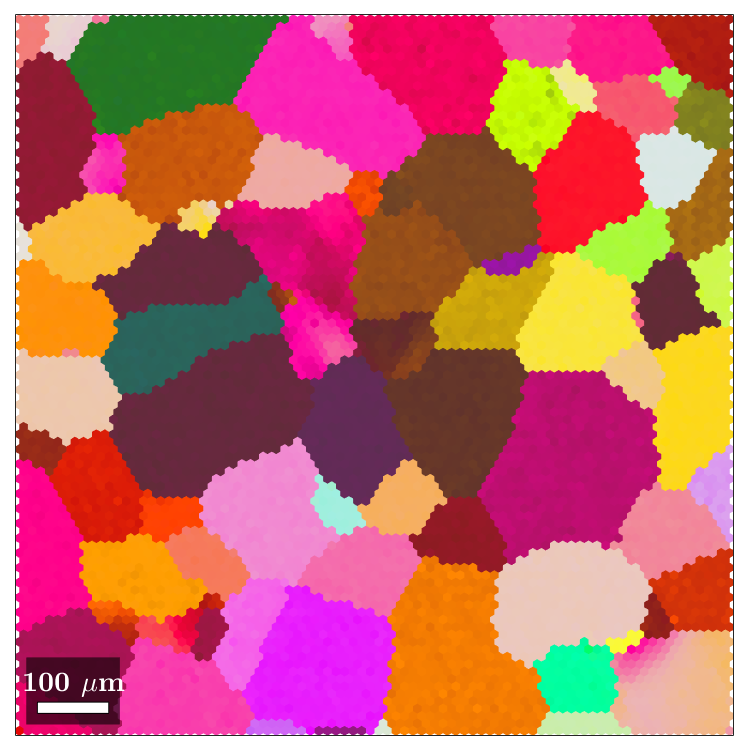

  I'm going to colorize the orientation data with the 
  standard MTEX ipf colorkey. To view the colorkey do:
 
  ipfKey = ipfColorKey(ori_variable_name)
  plot(ipfKey)


figure()
plot(ebsd, ebsd.orientations)

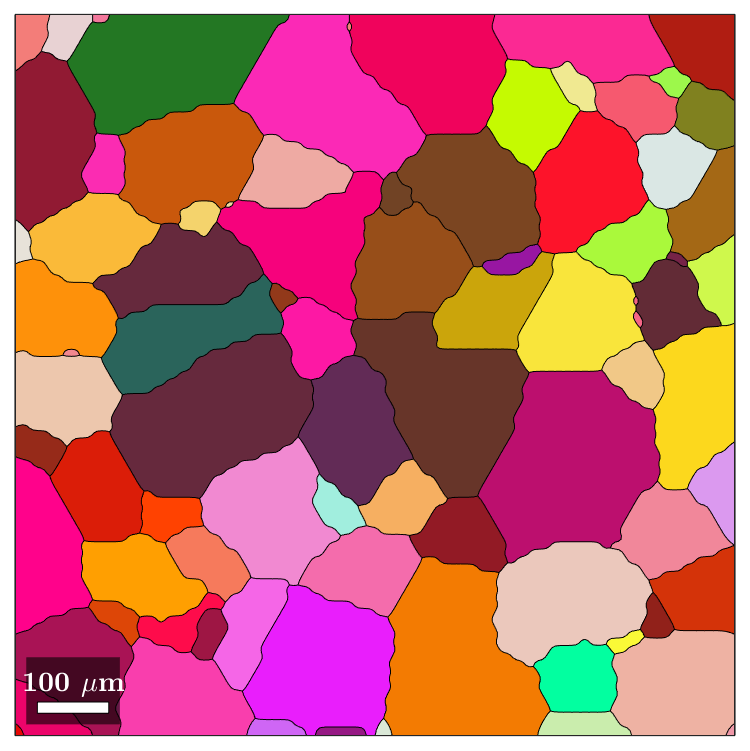

[grains,ebsd.grainId] = calcGrains(ebsd('indexed'),'angle',15*degree);
grains = smooth(grains,5);
colors = ipfKey.orientation2color(grains.meanOrientation);
figure()
plot(grains, colors)

% ipfKey = ipfColorKey(ebsd.orientations)
% plot(ipfKey)
% edsdtrial = ebsd(2)

ori = ebsd.orientations;
odf = calcDensity(ori)

 
odf = SO3FunHarmonic (Titanium (Alpha) → xyz)
  bandwidth: 25
  weight: 1
 


plot(odf)

#### MODELOS ODF

figure();
odf = fibreODF(fibre.gamma(odf.CS))

 
odf = SO3FunCBF (Titanium (Alpha) → xyz)
 
  kernel: de la Vallee Poussin, halfwidth 10°
  fibre : (-1-12-1) || 0,0,-1
  weight: 1
 


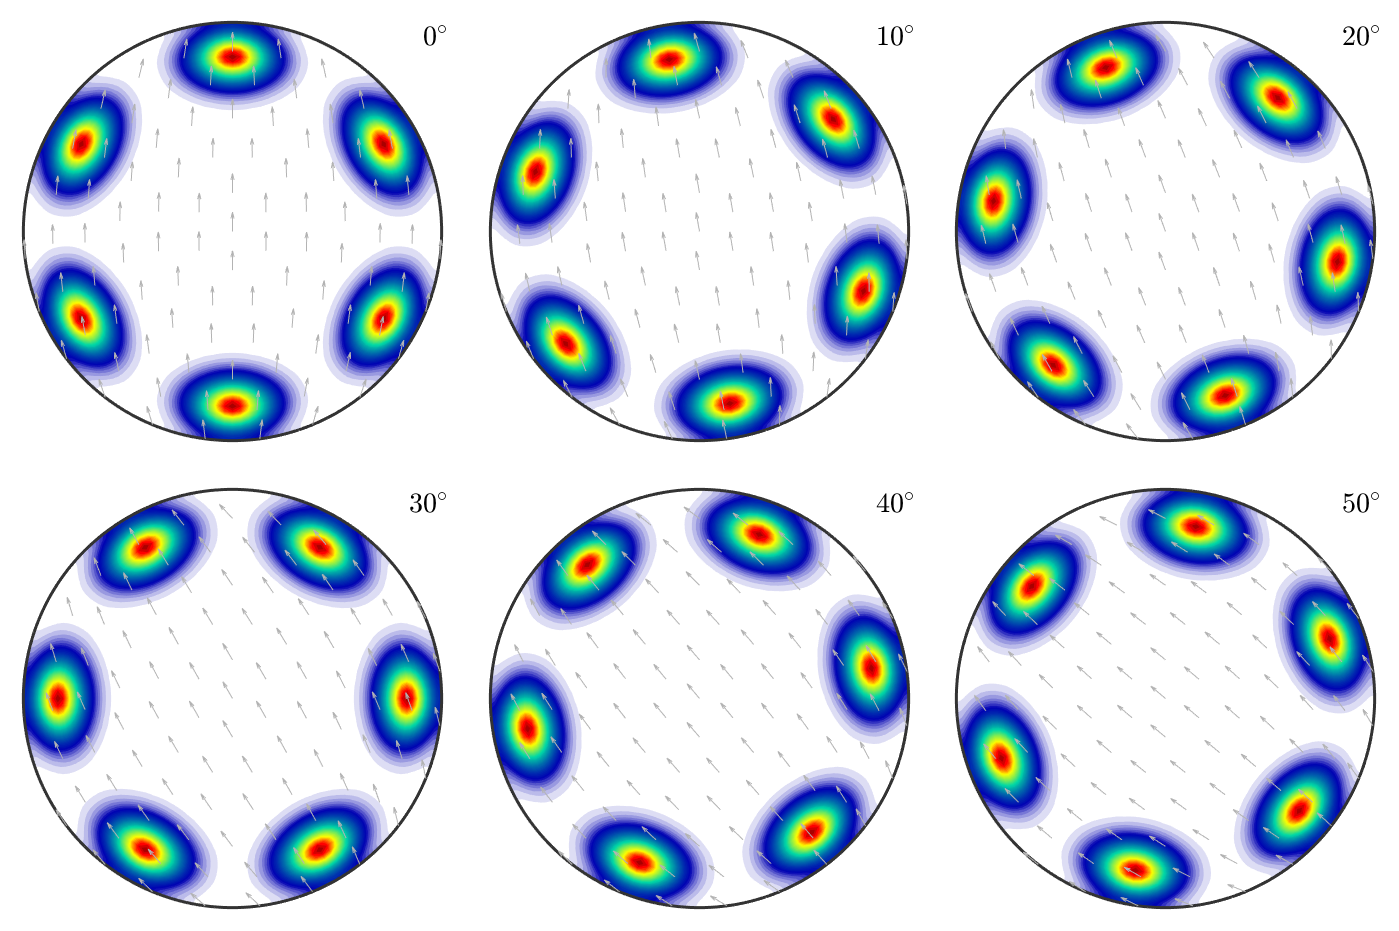

plot(odf,'sigma')


figure();
cs = crystalSymmetry('432');
ori = orientation.byMiller([1,2,2],[2,2,1],cs);
psi = SO3vonMisesFisherKernel('halfwidth',10*degree);
odf1 = unimodalODF(ori,psi)

 
odf1 = SO3FunRBF (432 → xyz)
 
  unimodal component
  kernel: van Mises Fisher, halfwidth 10°
  center: 1 orientations
 
  Bunge Euler angles in degree
     phi1     Phi    phi2  weight
  116.565 48.1897 26.5651       1
 


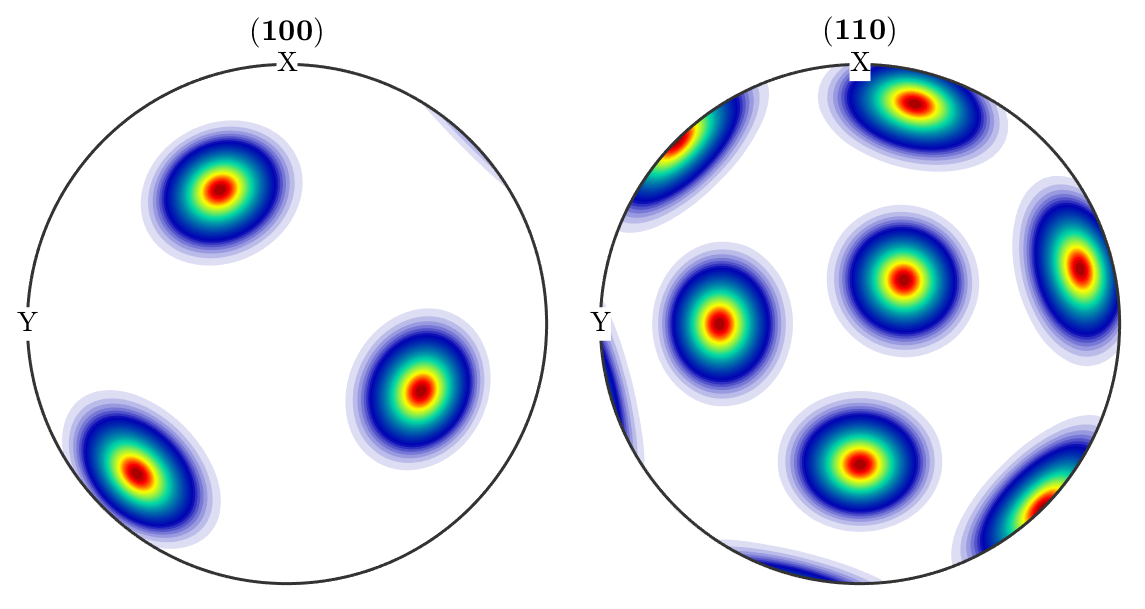

plotPDF(odf1,[Miller(1,0,0,cs),Miller(1,1,0,cs)],'antipodal')


figure();
ori2 = orientation.byMiller([1,1,2],[0,2,1],cs)

 
ori2 = orientation (432 → xyz)
 
  Bunge Euler angles in degree
     phi1     Phi    phi2
  309.232 35.2644      45
 


odf2 = unimodalODF(ori2,psi)

 
odf2 = SO3FunRBF (432 → xyz)
 
  unimodal component
  kernel: van Mises Fisher, halfwidth 10°
  center: 1 orientations
 
  Bunge Euler angles in degree
     phi1     Phi    phi2  weight
  309.232 35.2644      45       1
 


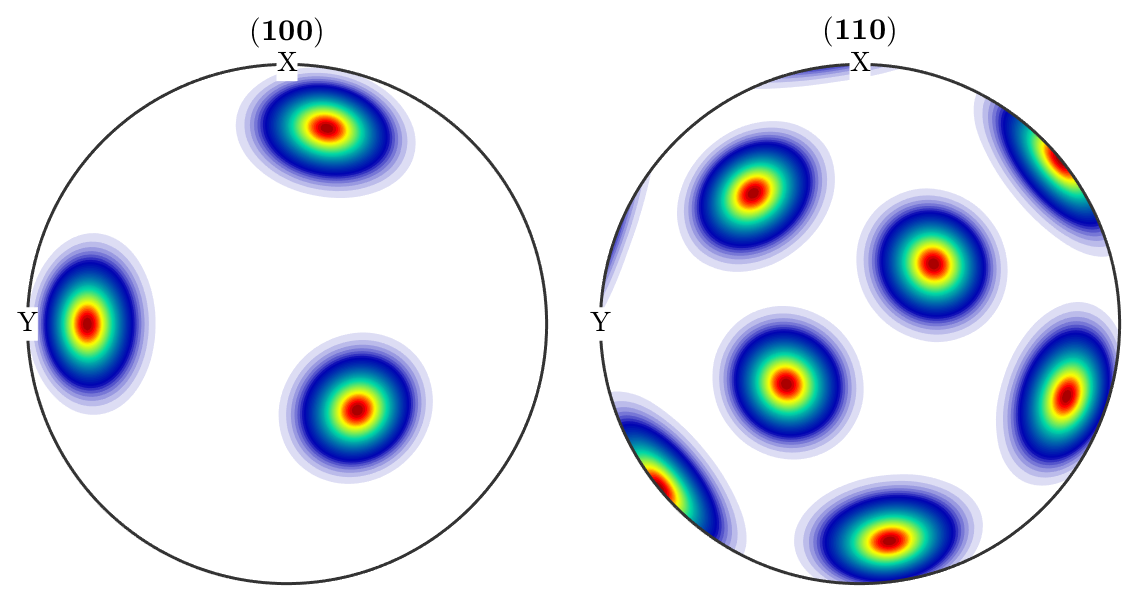

plotPDF(odf2,[Miller(1,0,0,cs),Miller(1,1,0,cs)],'antipodal')


figure();
odf4 = SO3FunRBF.example

 
odf4 = SO3FunRBF (-3m1 → xyz)
 
  multimodal components
  kernel: de la Vallee Poussin, halfwidth 5°
  center: 19848 orientations, resolution: 5°
  weight: 1
 


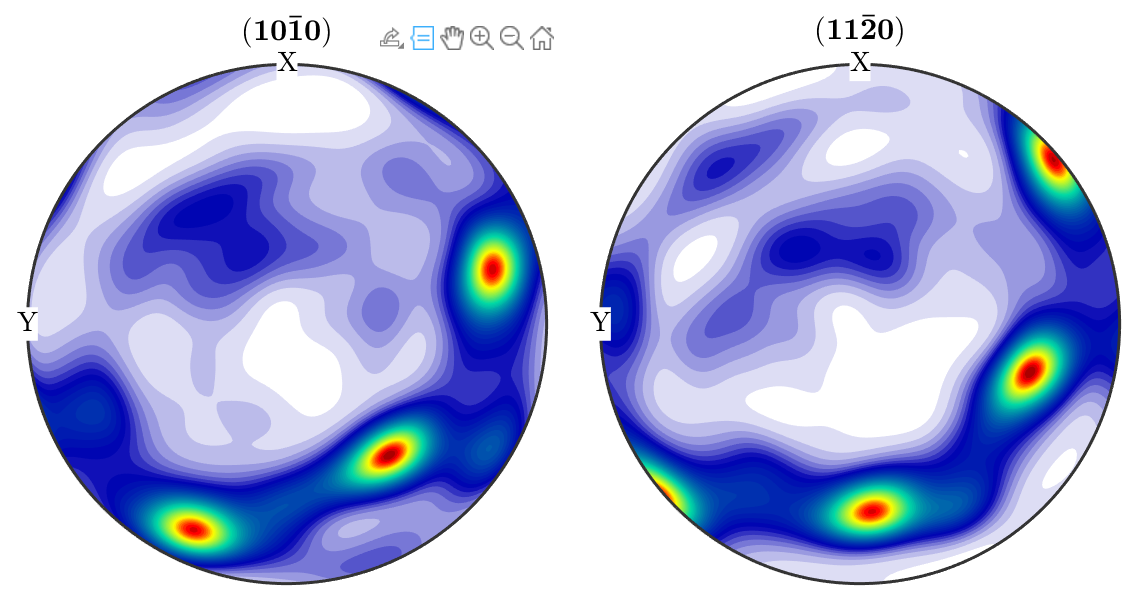

plotPDF(odf4,[Miller(1,0,0,odf4.CS),Miller(1,1,0,odf4.CS)],'antipodal')

Orientations, crystal symmetry

cs = crystalSymmetry.load('Cu-Copper.cif')

 
cs = crystalSymmetry
 
  mineral : Copper       
  symmetry: m-3m         
  elements: 48           
  a, b, c : 3.6, 3.6, 3.6
 


cs = crystalSymmetry('O')

 
cs = crystalSymmetry
 
  symmetry: 432    
  elements: 24     
  a, b, c : 1, 1, 1
 


mtexdata martensite

 
ebsd = EBSD
 
 Phase  Orientations         Mineral         Color  Symmetry  Crystal reference frame
     0   92415 (27%)      notIndexed                                                 
     1  251187 (73%)  Iron bcc (old)  LightSkyBlue       432                         
 
 Properties: bands, bc, bs, error, mad, reliabilityindex, x, y
 Scan unit : um
 cprInfo: show struct
 


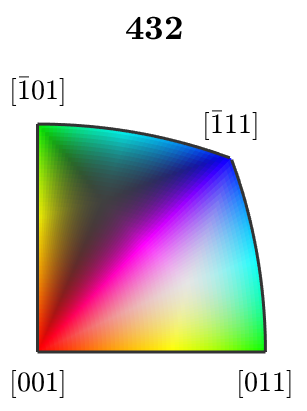

ipfKey = ipfHSVKey(ebsd);
plot(ipfKey)

mtexdata olivine

 
ebsd = EBSD
 
 Phase  Orientations       Mineral         Color  Symmetry  Crystal reference frame
     1   44953 (90%)       olivine  LightSkyBlue       222                         
     2   1370 (2.8%)      Dolomite  DarkSeaGreen         3       X||a, Y||b*, Z||c*
     3   2311 (4.6%)     Enstatite     Goldenrod       222                         
     4   1095 (2.2%)  Chalcopyrite    LightCoral       422                         
 
 Properties: ci, fit, iq, sem_signal, unknown1, unknown2, unknown3, unknown4, x, y, oldId
 Scan unit : um
 


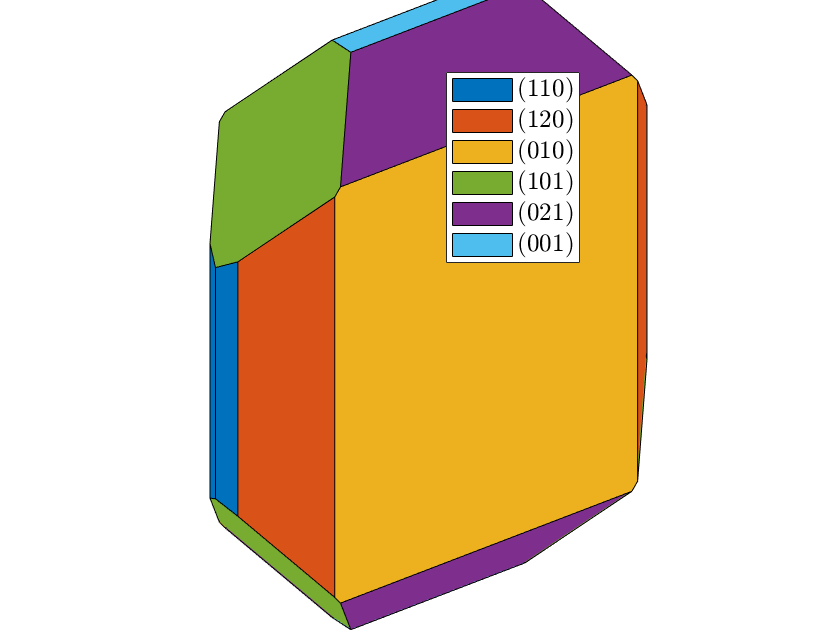

ebsd('olivine').CS = ebsd('olivine').CS.Laue;
cS = crystalShape.olivine;
plot(cS,'colored')

cS = crystalShape(6);

Dot indexing is not supported for variables of this type.

Error in crystalShape/update (line 63)
      N = unique(vector3d(N.symmetrise),'stable');

Error in crystalShape (line 50)
      cS = cS.update;

plot(cS,'colored')


cs = crystalSymmetry.load('SS316.cif')

Error using assert
Assertion failed.

Error in loadCIF (line 89)
assert(~isempty(group));

Error in crystalSymmetry.load (line 22)
  cs = loadCIF(fname,varargin{:});

plot(cs,'colored')

crystalSymmetry('austenite')

Error using assert
Assertion failed.

Error in hms2point (line 14)
assert(any(strcmp(s(1),{'A','B','C','F','I','P','R'})));

Error in findsymmetry (line 18)
  id = findsymmetry(hms2point(name));

Error in 

n = 100;
x = repelem(linspace(0,1,10),10)

x =          0         0         0         0         0         0         0         0         0         0    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.2222    0.2222    0.2222    0.2222    0.2222    0.2222    0.2222    0.2222    0.2222    0.2222    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444


y = repelem(linspace(0,1,10),10)

y =          0         0         0         0         0         0         0         0         0         0    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.2222    0.2222    0.2222    0.2222    0.2222    0.2222    0.2222    0.2222    0.2222    0.2222    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444


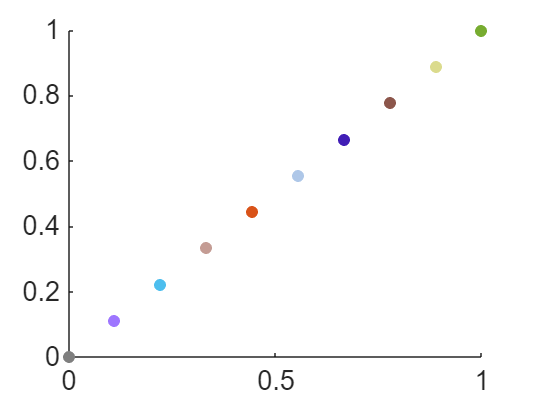

figure
hold on
for i = 1:100
    scatter(x(i),y(i),"filled",'Color',[x(i),x(i),x(i)])
end
hold off

x = [10 25 4 10 9 4 4]

x =     10    25     4    10     9     4     4


[a,b]=hist(x,unique(x))

a =      3     1     2     1


b =      4     9    10    25
